# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.2  最优化

#### 3.2.13 信頼域算法实现数据拟合

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

   100


  858.9244
    8.1254
    4.7651
   47.5910
    1.2569


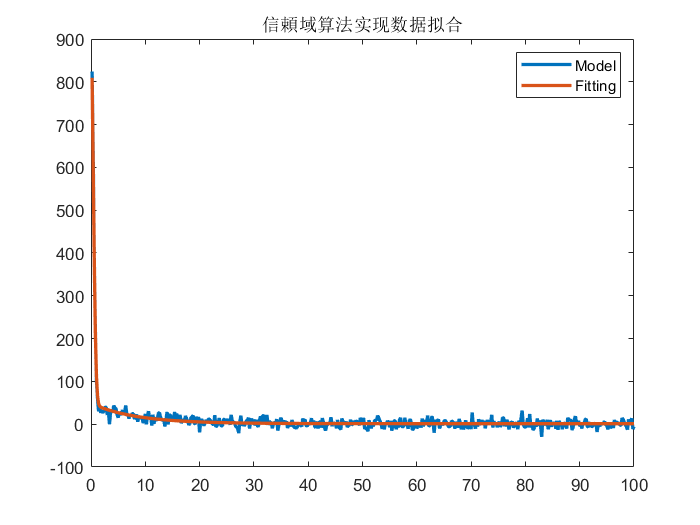

clear; clc
% Model
x = [0.5, 0.5, 0.5, 0.5, 0.01]';
NE = 500;
t = 0.2 * (1 : NE)';
Et = 900 * exp(-t / 10 - 0.5 * 5 * t.^2) + 40 * exp(- t / 10) + 1;
maxSig = max(Et);
ratio = 0.01;
Et = Et + ratio * maxSig * randn(NE, 1);
% t = (-10 : 10)';
% Et = 5 * sin(t) + 10 * cos(2 * t);
% x = [1.6, 1.4, 6.2, 1.7]';
% Normalization
maxi = max(Et);
Et = Et / maxi;   
maxiter = 100;
iter = 0;
Delta = 1;
g = Jfun(x, t)' * fun(x, t, Et);
while iter < maxiter
    iter = iter + 1;
    if iter == maxiter || norm(fun(x, t, Et), Inf) < 1e-6 || norm(g, Inf) < 1e-6 || Delta <= 1e-6 * (norm(x) + 1e-6)
        disp(iter);
        x(1) = maxi * x(1);
        x(4) = maxi * x(4);
        x(5) = maxi * x(5);
        disp(x);
        % Draw
        Et = maxi * Et;
        fitSig = x(1) * exp(-t / x(2) - 0.5 * x(3) * t.^2) + x(4) * exp(- t / x(2)) + x(5);
        plot(t, Et, t, fitSig, 'LineWidth', 2);
        legend('Model', 'Fitting');
        title('信頼域算法实现数据拟合');
        break;
    end
    J = Jfun(x, t);
    f = fun(x, t, Et);
    g = J' * f;
    alpha = sumsqr(g) / sumsqr(J * g);
    hsd = -g;
    hgn = SolveEquations(J'*J, -g);
    % Dog Leg Method
    if norm(hgn) <= Delta
        hdl = hgn;
    elseif norm(alpha * hsd) >= Delta
        hdl = Delta / norm(hsd) * hsd;
    else
        a = alpha * hsd;
        b = hgn;
        c = a' * (b - a);
        beta = (-c + sqrt(c^2 + sumsqr(b - a) * (Delta^2 - sumsqr(a)))) / sumsqr(b - a);
        hdl = a + beta * (b - a);
    end
    xnew = x + hdl;
    dF = Fun(x, t, Et) - Fun(xnew, t, Et);
    if norm(hgn) <= Delta
        dL = Fun(x, t, Et);
    elseif norm(alpha * hsd) >= Delta
        dL = Delta * (2 * sumsqr(alpha * g) - Delta) / ( 2*alpha);
    else
        dL = 0.5 * alpha * (1 - beta)^2 * sumsqr(g) + beta * (2 - beta) * Fun(x, t, Et);
    end
    rou = dF / dL;
    if rou > 0
        x = xnew;
    end
    if rou > 0.75
        Delta = max(Delta, 3 * norm(hdl));
    elseif rou < 0.25
        Delta = Delta / 2;
    end
end

function x = SolveEquations(A, y)
[u, s, v] = svd(A);
s(s < 1e-10) = 0;
for i = 1 : length(s)
    if s(i, i) > 0
        s(i, i) = 1 / s(i, i);
    end
end
x = v * s * u' * y;
end


function y = Fun(x, t, Et)
y = 0.5 * sumsqr(fun(x, t, Et));
end


function y = fun(x, t, Et)
y = x(1) * exp(-t / x(2) - 0.5 * x(3) * t.^2) + x(4) * exp(- t / x(2)) + x(5) - Et;
% y = x(1) * sin(x(2) * t) + x(3) * cos(x(4) * t) - Et;
end


function y = Jfun(x, t)
p = x;
fp1 = exp(- t / p(2) - 0.5 * p(3) * t.^2);
fp2 = (p(4) * t .* exp(-t / p(2))) / p(2)^2 + (p(1) * t .* exp(- t / p(2) - 0.5 * p(3) * t.^2)) / p(2)^2;
fp3 = -0.5 * p(1) * t.^2 .* exp(- t / p(2) - 0.5 * p(3) * t.^2);
fp4 = exp(-t / p(2));
y = [fp1, fp2, fp3, fp4, ones(size(fp1))];
% y = [sin(x(2) * t), x(1) * t .* cos(x(2) * t), cos(x(4) * t), -x(3) * t .* sin(x(4) * t)];
end